- Non-linear observer

                   
$$\begin{array}{l}
{\dot{x} }_1 =x_{2\;} \\
\dot{x} {\;}_{2\;} =-x_{1\;} -2x_{2\;} +0\ldotp 25x_1^2 x_{2\;} +0\ldotp 2\;\mathrm{sin}\;\left(2t\right)\;
\end{array}$$


  %%% Here I should define the output for design "Observer" 

                    
$$y=x_{1\;}$$


- Define the system and calculate jacobian


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;A{\left(t\right)}={{\left({\left[\begin{array}{cc}
\frac{\partial f_1 {\left(x_1 ,x_2 \right)}}{\partial x_1 } & \frac{\partial f_1 {\left(x_1 ,x_2 \right)}}{\partial x_2 }\\
\frac{\partial f_2 {\left(x_1 ,x_2 \right)}}{\partial x_1 } & \frac{\partial f_2 {\left(x_1 ,x_2 \right)}}{\partial x_2 }
\end{array}\right]}\right|}}_{\hat{x} }$$


clear all,close all,clc;

%% step-1 compute A(t)  
syms x1 x2 real

f1=x2;
f2=-x1-2*x2+0.25*(x1^2)*x2;

A_t=jacobian([f1;f2],[x1;x2]) 

syms x1hat x2hat real
A_t=subs(A_t,[x1 x2],[x1hat x2hat])


   2.  Riccati Equation and  define parameters

           
$$\dot{P} =\textrm{Ap}+{\textrm{PA}}^{T\;} +Q-{\textrm{PC}}^{T\;} R^{-1\;} \textrm{CP}$$


%% step-2 decide Q,P(0),R
Q=eye(2)    % nxn
R=eye(1)    % pxp
C=[1,0]
B=[0;1] 

   3.   The dynamics of Riccati equation  step-3 Pdot-dyns

 This will be solved using ode45 in the following matlab-function 


syms p11 p12 p22 real
P=[p11,p12;p12,p22]
Pdot=[A_t*P]+[A_t*P]'+Q-P*C'*inv(R)*C*P

Pdot(1,1)   % p11_dot
Pdot(1,2)   % p12_dot
Pdot(2,2)   % p22_dot

 4.  Observer gain

        
$$H={\textrm{PC}}^{T\;} R^{-1}$$


%% step-4 compute H(t)
H_t=P*C'*inv(R)

5. The innovation proccess 

    
$$H\left(y\;-\textrm{Cx}\right)=H\left(x_{1\;} -\hat{x_{1\;} } \right)$$


%% step-5 explicity write down xhat_dot-dyns
H_t*[x1-x1hat]

6. The Observer dyns

[subs(f1,[x1 x2],[x1hat x2hat]);subs(f2,[x1 x2],[x1hat x2hat])]+H_t*[x1-x1hat]


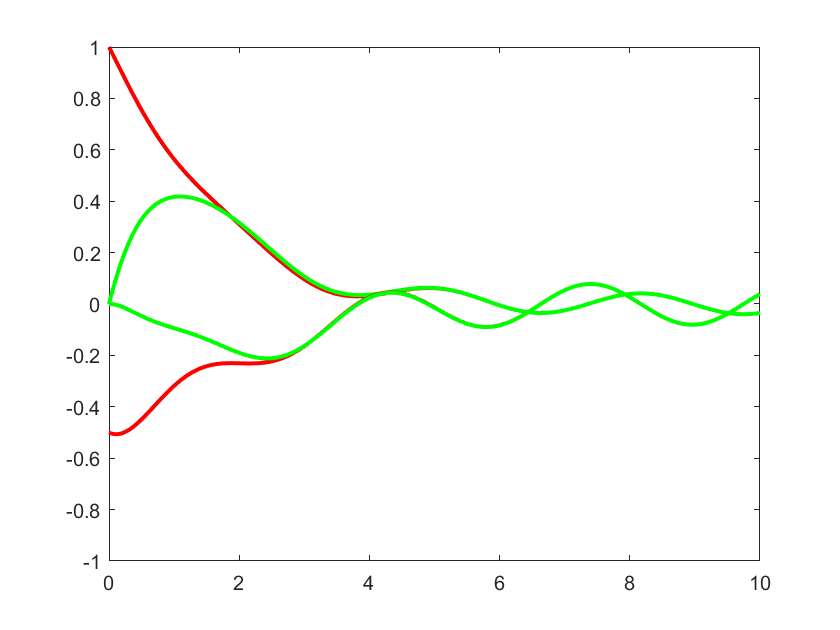


%%

fig1=figure(1);fig1.Color=[1,1,1];
ax1=axes('Parent',fig1);
    set(0,'CurrentFigure',fig1);
    set(fig1,'currentaxes',ax1);
    
% Simulation 
tspan=[0:0.01:10]; 
% x0=randn(7,1)*1; x0(5)=1;x0(6)=0;x0(7)=1;

% initialization : define initial values
% real plant
x0(1) = 1; x0(2) =-0.5;
% Observer 
x0(3)=0; x0(4)=0;
%Riccati P(0)
x0(5)=1;x0(6)=0;x0(7)=1;

% ODE solver
[t,x]=ode45(@(t,x) odefcn(t,x),tspan,x0);
x1_vec=x(:,1);x2_vec=x(:,2);
x1hat_vec=x(:,3);x2hat_vec=x(:,4);
plot(t,x1_vec,'r-','LineWidth',[2],"Parent",ax1);hold on;
plot(t,x1hat_vec,'g-','LineWidth',[2],"Parent",ax1);hold on;
plot(t,x2_vec,'r-','LineWidth',[2],"Parent",ax1);hold on;
plot(t,x2hat_vec,'g-','LineWidth',[2],"Parent",ax1);hold on;
hold on;yline(1);yline(-1);

% end

function xdot=odefcn(t,x)
% w=interp1(wt,w,t);
xdot=zeros(7,1);
x1=x(1);x2=x(2);
x1hat=x(3);x2hat=x(4);
p11=x(5);p12=x(6);p22=x(7);

f1=x2;
f2=-x1-2*x2+0.25*(x1)^2*(x2)+0.2*sin(2*t);
x1dot=f1;
x2dot=f2;
y=x1;
x1hat_dot=x2hat + p11*(x1 - x1hat);
x2hat_dot=- 2*x2hat - x1hat + (x1hat^2*x2hat)/4+0.2*sin(2*t)+p12*(x1 - x1hat);
%
p11dot=- p11^2 + 2*p12 + 1;
p12dot=p22 - p11*p12 + p12*(x1hat^2/4 - 2) + p11*((x1hat*x2hat)/2 - 1);
p22dot=2*p22*(x1hat^2/4 - 2) + 2*p12*((x1hat*x2hat)/2 - 1) - p12^2 + 1;


xdot(1)=f1;
xdot(2)=f2;
xdot(3)=x1hat_dot;
xdot(4)=x2hat_dot;
xdot(5)=p11dot;
xdot(6)=p12dot;
xdot(7)=p22dot;
end